# Decentralized OPF

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "dablab_files", filesep, "DOPF_1Phase_dablab", filesep) )
    addpath('functions\')
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
    
systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

numTimePeriods = 5;
delta_t = 0.25; % 15 minutes = 0.25 hours
fprintf("A total of %d time-periods (of %f minutes each, so %f hours in total) " + ...
    "will be run.\n", numTimePeriods, delta_t*60, delta_t*numTimePeriods);

A total of 5 time-periods (of 15.000000 minutes each, so 75.000000 hours in total) will be run.


stepVals = 1:1:numTimePeriods;
% etta_C = 0.80;
% etta_D = 0.80;

% loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 20; % Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
saveSimulationResults = true;
displaySimulationResultPlots = true;
saveSimulationResultPlots = false;

namesSys = ["PLoss", "QLoss", "delV", "PSubs", "QSubs", "QDER", "SOC"];
namesAreas = ["P12", "Q12", "V", "PSaving"];
namesNode = ["P_c", "P_d", "B"];

[lambdas, PLosses, QLosses] = deal( zeros(numTimePeriods, 1) );

[P12s, Q12s, V1s] = deal( zeros(numTimePeriods, numAreas));

[P_ij, Q_ij, S_ij, l_ij, v_j, qD_j, B_j, Pc_j, Pd_j, qB_j] = deal( zeros(numTimePeriods, numAreas, N));

% CVR = [0; 0]; % as opposed to [0.6; 3.0]

% load_mult = 1;
% gen_mult = 1;

verbose = true;
logging = false;
% V_min = 0.95;
% V_max = 1.05;

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
S_allRelationships = CBTable.S_childArea;

S_parent = zeros(numAreas, 1);
S_Areas = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
qD_Full_Areas = zeros(N, numAreas);
N_Areas = zeros(numAreas, 1);
m_Areas = zeros(numAreas, 1);

#### Start with the algorithm

********Running OPF for the system for Time Period = 1.********


Plotting for Area 1:
This area has only the substation as its 'parent area'.
This area has 2 child areas, which include the Areas: Area 2 and Areas 3.


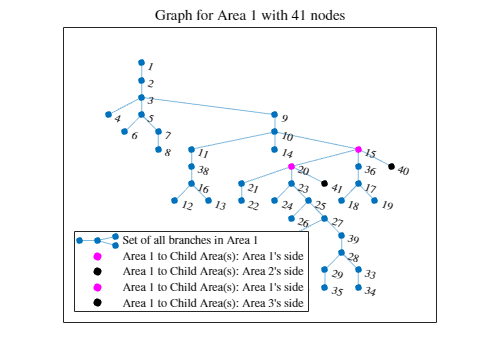

Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 1:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 1:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 1:  Oh no! x0_NoLoss(132) < lb(132) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 1:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 1:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 1: x0_NoLoss within limits anyway? More like MATLAB stupid? Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
Time

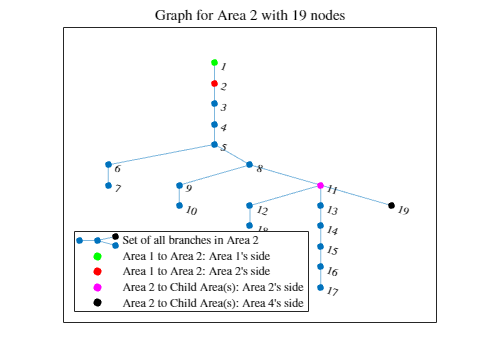

Number of DERs in Area 2 : 12.
Number of Batteries in Area 2 : 12.
First Time Period, will initialize Battery SOCs for Area 2 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 2 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 1, Area = 2 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 2 and itr = 1: x0_NoLoss within limits. Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 1, Area = 2 and itr = 1: Performing Initialization Phase 2
TimePeriod = 1, Area = 2 and itr = 1: Lossless Initialization WITH batteries accomplished.
TimePeriod = 1, Area = 2 and itr = 1:  x0 within limits. Initialization successful. Proceeding to solving for the full optimization problem.
TimePeriod = 1, Area = 2 and itr = 1:  Now solving for the real deal.
TimePeriod = 1, Area = 2 and itr = 1: Projected savings in substation power flow by using batteries: 53.810953 percent.
Plotting for Area 3:
This a

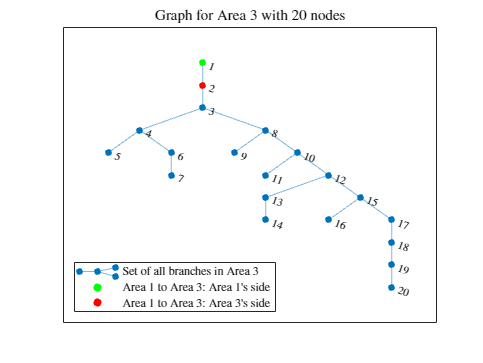

Number of DERs in Area 3 : 14.
Number of Batteries in Area 3 : 14.
First Time Period, will initialize Battery SOCs for Area 3 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 3 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 1, Area = 3 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 3 and itr = 1: x0_NoLoss within limits. Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 1, Area = 3 and itr = 1: Performing Initialization Phase 2
TimePeriod = 1, Area = 3 and itr = 1: Lossless Initialization WITH batteries accomplished.
TimePeriod = 1, Area = 3 and itr = 1:  x0 within limits. Initialization successful. Proceeding to solving for the full optimization problem.
TimePeriod = 1, Area = 3 and itr = 1:  Now solving for the real deal.
TimePeriod = 1, Area = 3 and itr = 1: Projected savings in substation power flow by using batteries: 53.822028 percent.
Plotting for Area 4:
This a

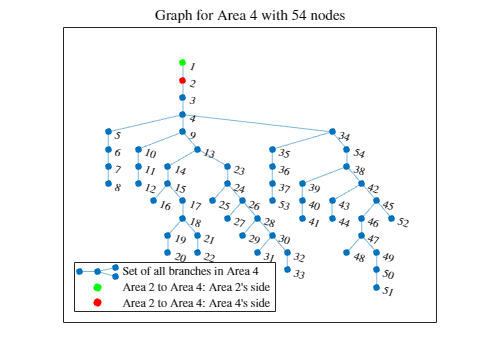

Number of DERs in Area 4 : 36.
Number of Batteries in Area 4 : 36.
First Time Period, will initialize Battery SOCs for Area 4 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 4 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 1, Area = 4 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(170) < lb(170) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(178) < lb(178) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(179) < lb(179) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(180) < lb(180) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(181) < lb(181) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(183) < lb(183) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 4 and itr = 1:  Oh no! x0_NoLoss(186) < lb(186) as -0.0030

Still yet to converge after 1 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 2: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 2: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 2:  Oh no! x0_NoLoss(142) < lb(142) as -0.0015

Still yet to converge after 2 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 3: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 3: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 3:  Oh no! x0_NoLoss(142) < lb(142) as -0.0015

Still yet to converge after 3 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 4: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 4: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 4:  Oh no! x0_NoLoss(142) < lb(142) as -0.0015

Still yet to converge after 4 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 5: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 5: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 5:  Oh no! x0_NoLoss(142) < lb(142) as -0.0015

Still yet to converge after 5 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
First Time Period, will initialize Battery SOCs for Area 1 at the middle of the permissible bandwidth.
TimePeriod = 1, Area = 1 and itr = 6: Performing Initialization Phase 1.
TimePeriod = 1, Area = 1 and itr = 6: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 1, Area = 1 and itr = 6:  Oh no! x0_NoLoss(142) < lb(142) as -0.0015

Converged in 6 iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


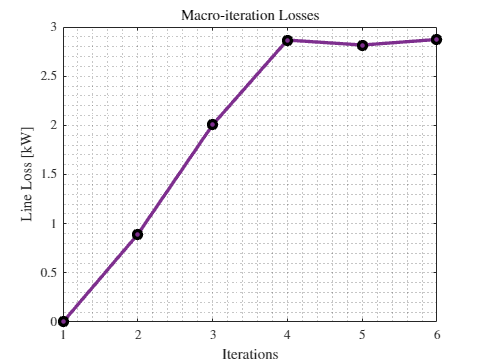

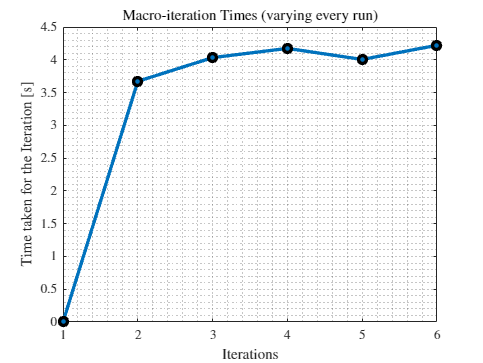

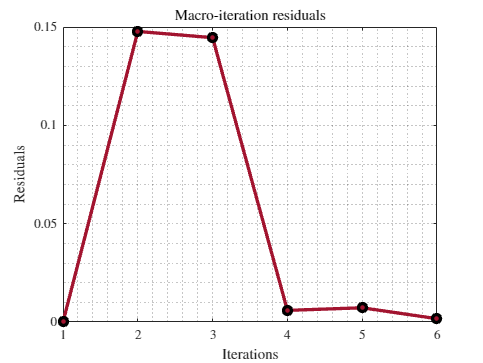

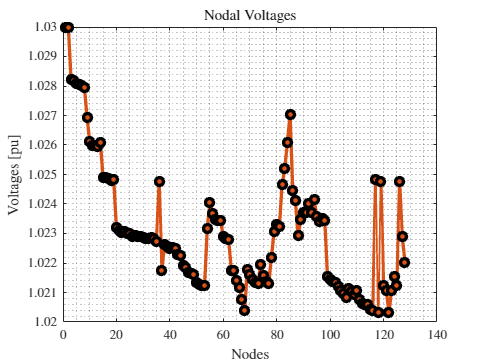

------------------------------------------------------------
Time Period: 1
Line Loss: 2.8734 kW
Substation Power: 351.8285 kW
Number of Iterations: 6
Time to Solve: 13.1742s
------------------------------------------------------------


********Running OPF for the system for Time Period = 2.********


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 2, Area = 1 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 2, Area = 1 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 2, Area = 1 and itr = 1:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 2, Area = 1 and itr = 1: x0_NoLoss within limits anyway? More like MATLAB 

Converged in 1 iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


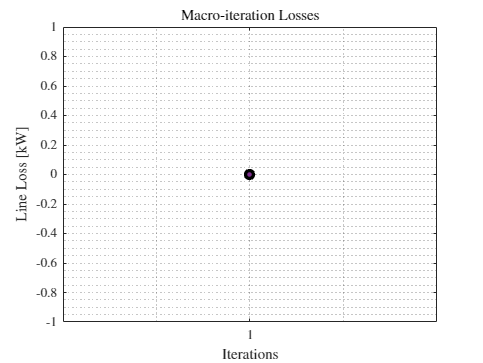

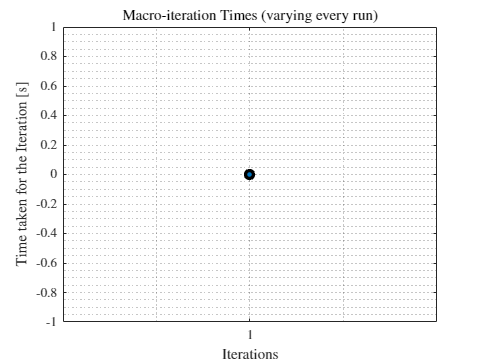

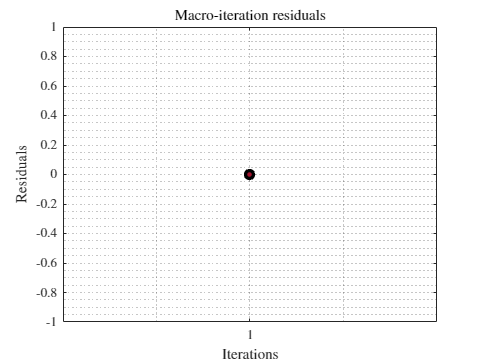

------------------------------------------------------------
Time Period: 2
Line Loss: 0 kW
Substation Power: 351.8285 kW
Number of Iterations: 1
Time to Solve: 0s
------------------------------------------------------------


********Running OPF for the system for Time Period = 3.********


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 3, Area = 1 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 3, Area = 1 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 3, Area = 1 and itr = 1:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 3, Area = 1 and itr = 1: x0_NoLoss within limits anyway? More like MATLAB 

Converged in 1 iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


------------------------------------------------------------
Time Period: 3
Line Loss: 0 kW
Substation Power: 351.8285 kW
Number of Iterations: 1
Time to Solve: 0s
------------------------------------------------------------


********Running OPF for the system for Time Period = 4.********


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 4, Area = 1 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 4, Area = 1 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 4, Area = 1 and itr = 1:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 4, Area = 1 and itr = 1: x0_NoLoss within limits anyway? More like MATLAB 

Converged in 1 iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


------------------------------------------------------------
Time Period: 4
Line Loss: 0 kW
Substation Power: 351.8285 kW
Number of Iterations: 1
Time to Solve: 0s
------------------------------------------------------------


********Running OPF for the system for Time Period = 5.********


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 1: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 1: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 1:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 1: x0_NoLoss within limits anyway? More like MATLAB 

Still yet to converge after 1 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 2: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 2: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(133) < lb(133) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(136) < lb(136) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(137) < lb(137) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 2:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 2: x0_NoLoss within limits anyway? More like MATLAB 

Still yet to converge after 2 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 3: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 3: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 3:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 3:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 3:  Oh no! x0_NoLoss(132) < lb(132) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 3:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 3:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 3: x0_NoLoss within limits anyway? More like MATLAB stupid? Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 5, Area = 1 and itr = 3: Performing Initialization Phase 2
TimePeriod = 5, Area = 1 and itr = 

Still yet to converge after 3 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 4: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 4: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 4:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 4:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 4:  Oh no! x0_NoLoss(132) < lb(132) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 4:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 4:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 4: x0_NoLoss within limits anyway? More like MATLAB stupid? Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 5, Area = 1 and itr = 4: Performing Initialization Phase 2
TimePeriod = 5, Area = 1 and itr = 

Still yet to converge after 4 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 5: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 5: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 5:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 5:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 5:  Oh no! x0_NoLoss(132) < lb(132) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 5:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 5:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 5: x0_NoLoss within limits anyway? More like MATLAB stupid? Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 5, Area = 1 and itr = 5: Performing Initialization Phase 2
TimePeriod = 5, Area = 1 and itr = 

Still yet to converge after 5 iterations, continuing.


Number of DERs in Area 1 : 23.
Number of Batteries in Area 1 : 23.
TimePeriod = 5, Area = 1 and itr = 6: Performing Initialization Phase 1.
TimePeriod = 5, Area = 1 and itr = 6: Lossless Initialization WITHOUT batteries accomplished.
TimePeriod = 5, Area = 1 and itr = 6:  Oh no! x0_NoLoss(129) < lb(129) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 6:  Oh no! x0_NoLoss(130) < lb(130) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 6:  Oh no! x0_NoLoss(132) < lb(132) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 6:  Oh no! x0_NoLoss(140) < lb(140) as -0.003095 < -0.003095.
TimePeriod = 5, Area = 1 and itr = 6:  Oh no! x0_NoLoss(142) < lb(142) as -0.001548 < -0.001548.
TimePeriod = 5, Area = 1 and itr = 6: x0_NoLoss within limits anyway? More like MATLAB stupid? Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
TimePeriod = 5, Area = 1 and itr = 6: Performing Initialization Phase 2
TimePeriod = 5, Area = 1 and itr = 

Converged in 6 iterations!


Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


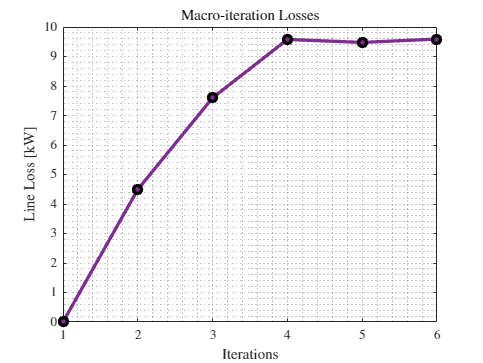

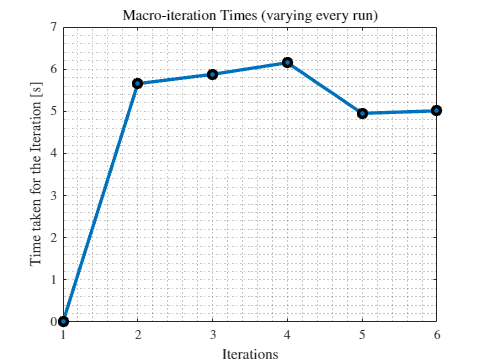

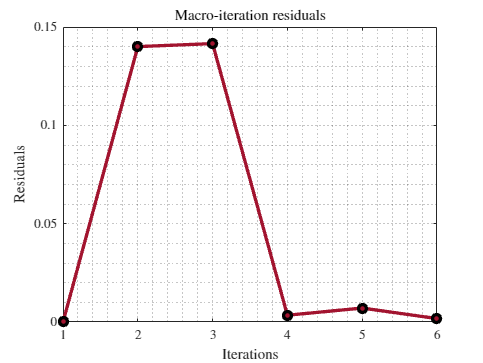

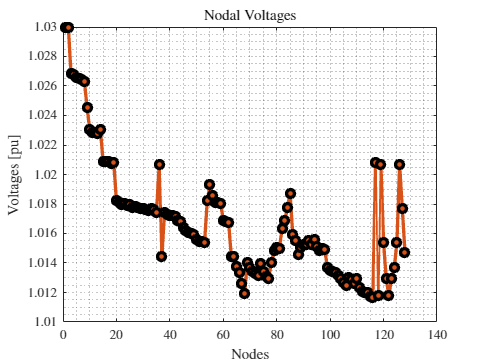

------------------------------------------------------------
Time Period: 5
Line Loss: 9.5926 kW
Substation Power: 700.5256 kW
Number of Iterations: 6
Time to Solve: 18.0542s
------------------------------------------------------------


for t = 1:numTimePeriods
    
    myfprintf(true, "********Running OPF for the system for Time Period = %d.********\n", t); %always true
    keepRunningIterations = true;
    itr = 1;
    time_dist = zeros(itrMax, numAreas);
    microIterationLosses = zeros(itrMax, numAreas);
    R_max = zeros(itrMax, 1);
    
    Se_iter = zeros(itrMax, numAreas);
    V_iter = zeros(itrMax, N, numUniqueParents);
    
    
    while keepRunningIterations
        for Area = 1:numAreas

            v2_parent_Area = v2_parent(Area);
            S_childAreas = S_allRelationships(CBTable.parentArea == Area);
    
            isLeaf_Area = isLeaf(Area);
            isRoot_Area = isRoot(Area);
            numChildAreas_Area = numChildAreas(Area);
            
            B0Vals_Area = B_j(t, Area, :);
    
            [xVals_Area, B0Vals_Area, ...
                microIterationLosses,  ...
                itr, time_dist, R_Area, T_Area, N_Area, m_Area, nDER_Area, nBatt_Area, busDataTable_Area, branchDataTable_Area] = ...
                NL_OPF_dist(v2_parent_Area, S_childAreas, B0Vals_Area, ...
                Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, ...
                numAreas, ...
                microIterationLosses, time_dist, t, itr,  ...
                CBTable, 'verbose', true, 'saveToFile', true);
            
            N_Areas(Area) = N_Area;
            m_Areas(Area) = m_Area;

            numVarsFull = [m_Area, m_Area, m_Area, N_Area, nDER_Area, nBatt_Area, nBatt_Area, nBatt_Area, nBatt_Area];
            ranges_Full = generateRangesFromValues(numVarsFull);

            indices_P = ranges_Full{1};
            indices_Q = ranges_Full{2};
            indices_l = ranges_Full{3};
            indices_vAll = ranges_Full{4};
            indices_v = indices_vAll(2:end);
            indices_qD = ranges_Full{5};
            indices_B = ranges_Full{6};
            indices_Pc = ranges_Full{7};
            indices_Pd = ranges_Full{8};
            indices_qB = ranges_Full{9};
            
            P_Area = xVals_Area(indices_P); %m_Areax1
            Q_Area = xVals_Area(indices_Q); %m_Areax1
            S_Area = complex(P_Area, Q_Area); %m_Areax1
            l_Area = xVals_Area(indices_l);
            vFull_Area = xVals_Area(indices_vAll); %N_Areax1
            v2_Area = vFull_Area;
            qD_Area = xVals_Area(indices_qD);
            B_Area = xVals_Area(indices_B);
            Pd_Area = xVals_Area(indices_Pd);
            Pc_Area = xVals_Area(indices_Pc);
            qB_Area = xVals_Area(indices_qB);

            P_ij(t, Area, 1:m_Area) = P_Area;
            Q_ij(t, Area, 1:m_Area) = Q_Area; %m_Areax1
            S_ij(t, Area, 1:m_Area) = complex(P_Area, Q_Area); %m_Areax1
            l_ij(t, Area, 1:m_Area) = l_Area;
            v_j(t, Area, 1:N_Area) = vFull_Area;
            qD_j(t, Area, 1:nDER_Area) = qD_Area;
            B_j(t, Area, 1:nBatt_Area) = B0Vals_Area;
            B_j(t+1, Area, 1:nBatt_Area) = B_Area;
            Pc_j(t, Area, 1:nBatt_Area) = Pc_Area;
            Pd_j(t, Area, 1:nBatt_Area) = Pd_Area;
            qB_j(t, Area, 1:nBatt_Area) = qB_Area;

            
            S_parent(Area) = S_Area(1);
            P12s(t, Area) = kVA_B*real(S_Area(1));
            Q12s(t, Area) = kVA_B*imag(S_Area(1));
            V1s(t, Area) = sqrt(v2_Area(1));
            % qD_Full_Areas(1:N_Area, Area) = qD_Full_Area;
            
            % v2(1:N_Area, Area) = v2_Area;   % Storing all the square of the node voltages
            v2(1:N_Area, Area) = vFull_Area;
            S_Areas(1:m_Area, Area) = S_Area;   % Storing all the S flow of the Area
    
            % SOC_Array(Area, 1:nBatt_Area, t+1) = BVals_Area;
            % B_j(t, Area, 1:nBatt_Area) = B0Vals_Area;
            % B_j(t+1, Area, 1:nBatt_Area) = BVals_Area;


            
        end
        
        
        for relationshipNum = 1 : numRelationships
    
            parentArea = CBTable.parentArea(relationshipNum);
            childArea = CBTable.childArea(relationshipNum);
            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            parentAreaOutflowingPower = S_Areas(parentAreaConnectingBus - 1, parentArea);
            childAreaInflowingPower = S_parent(childArea);
    
            powerflowDifference = parentAreaOutflowingPower - childAreaInflowingPower;
    
            parentAreaConnectingBusVoltage = v2(parentAreaConnectingBus, parentArea);
            childAreaConnectingBusVoltage = v2_parent(childArea);
    
            voltageDifference = parentAreaConnectingBusVoltage - childAreaConnectingBusVoltage;
    
            R_Area = [powerflowDifference; voltageDifference];
            
            if max(abs(R_Area)) > R_max(itr+1)
                R_max(itr+1) = max(abs(R_Area));
            end
    
        end
        
        if itr > itrMax
            % keepRunningIterations = false;
            error("Didn't converge even in %d iterations, terminating.\n", itrMax);
    
        elseif R_max(itr+1) < eps
            fprintf("Converged in %d iterations!\n", itr);
            keepRunningIterations = false;
            R_max = R_max(1:itr);
    
        else
            fprintf("Still yet to converge after %d iterations, continuing.\n", itr)
            %Communication-
            
            for relationshipNum = 1:numRelationships
                parentArea = CBTable.parentArea(relationshipNum);
                childArea = CBTable.childArea(relationshipNum);
                busParentTo = CBTable.conBus_parentAreaTo(relationshipNum);
                V_iter(itr+1, busParentTo, parentArea) = v2(busParentTo, parentArea) ;
                Se_iter(itr+1,childArea) = S_parent(childArea);
    
                if itr > 2
                    v2_parent(childArea) = a(2)*V_iter(itr-1, busParentTo, parentArea)+...
                        a(1)*V_iter(itr, busParentTo, parentArea)+...
                        (1-sum(a))*v2(busParentTo, parentArea) ;
    
                    S_allRelationships(relationshipNum) = a(2)*Se_iter(itr-1, childArea)+...
                        a(1)*Se_iter(itr, childArea)+...
                        (1-sum(a))*S_parent(childArea);
                else
    
                    v2_parent(childArea) = v2(busParentTo, parentArea);
                    S_allRelationships(relationshipNum) = S_parent(childArea);
    
                end
    
            end
    
            itr = itr + 1;
    
        end
    
    end
    
    N_ParentArea_Max = max(N_Areas(uniqueParents));
    Se_iter = Se_iter(1:itr, :);
    V_iter = V_iter(1:itr, 1:N_ParentArea_Max, uniqueParents);

    postProcessResults(N, numAreas, N_Areas, isRoot, v2, actualBusNums, ...
        microIterationLosses, t, itr, time_dist, kVA_B, displaySimulationResultPlots, ...
        R_max, saveSimulationResultPlots, systemName, S_Areas, start, saveSimulationResults);


end

grandTotalTime = toc(start)

grandTotalTime = 220.4320